# Initial Motor Test Results and Analysis

Date: 2023-08-10 

Author: Jonas Wagner

clear
close all
% Import transcribed results from video (data/vids/20230810_011619.mp4)
T = readtable("data\vids\motorTestData_20230810_011619.csv");
T.omega = (2*pi/60).*T.RPM;
T.P_in_W = T.Voltage_V .* T.Current_A;
T.P_out_W = T.Torque_Nm .* T.omega;
T.eta = T.P_out_W ./ T.P_in_W

T = 13×9 table
    Time_s    Voltage_V    Current_A    Torque_Nm    RPM    omega     P_in_W    P_out_W      eta  
    ______    _________    _________    _________    ___    ______    ______    _______    _______

      30        24.01        0.41          0.3       87     9.1106    9.8441    2.7332     0.27765
      40        24.01         0.5          0.4       78     8.1681    12.005    3.2673     0.27216
      50        24.01        0.49          0.4       78     8.1681    11.765    3.2673     0.27771
      60        24.01        0.47          0.4       78     8.1681    11.285    3.2673     0.28953
      70        24.01        0.47          0.4       76     7.9587    11.285    3.18

% Energy (J) = Power (W) * Time (s)
E_total_in = sum(10*T.P_in_W);
E_total_out = sum(10*T.P_out_W);
eta_total = E_total_out/E_total_in;
fprintf('Total Energy In: %0d W\n',round(E_total_in)); fprintf('Total Energy Out: %0d W\n',round(E_total_out)); fprintf('Total Efficiency: %.2f%%',100*eta_total)

Total Energy In: 1522 W
Total Energy Out: 383 W
Total Efficiency: 25.19%

## Plots

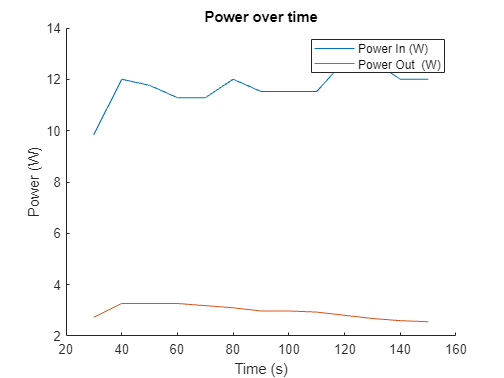

figure
hold on
plot(T.Time_s, T.P_in_W, DisplayName = "Power In (W)")
plot(T.Time_s, T.P_out_W, DisplayName = "Power Out  (W)")
title('Power over time')
xlabel('Time (s)')
ylabel('Power (W)')
legend

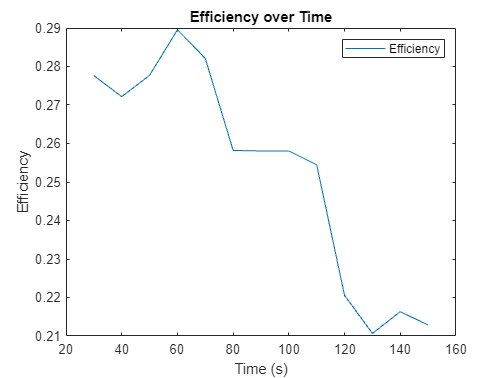


figure
plot(T.Time_s, T.eta, DisplayName="Efficiency")
title('Efficiency over Time')
xlabel('Time (s)')
ylabel('Efficiency')
legend